clc
clear
close all

load("sim_save.mat")

                  main_clock: [898×1 double]
            vehicle_position: [898×3 double]
            vehicle_velocity: [898×3 double]
        vehicle_acceleration: []
         vehicle_orientation: [898×3 double]
    vehicle_ang_acceleration: []
        vehicle_ang_velocity: [898×3 double]
                     F_rotor: [898×3 double]
                   F_gravity: [898×3 double]
             F_drag_cilinder: [898×3 double]
                     F_total: [898×3 double]
                     T_rotor: [898×1 double]
                     T_total: [898×3 double]
                 temperature: [898×1 double]
                    pressure: [898×1 double]
                     density: [898×1 double]
           dynamic_visvosity: [898×1 double]
         kinematic_viscosity: [898×1 double]
                 sound_speed: [898×1 double]
              rotor_velocity: [898×1 double]
          rotor_acceleration: []
      rotor_induced_velocity: [898×1 double]
               wind_velocity: [898×3 double]
 

close all

#### VEHICLE

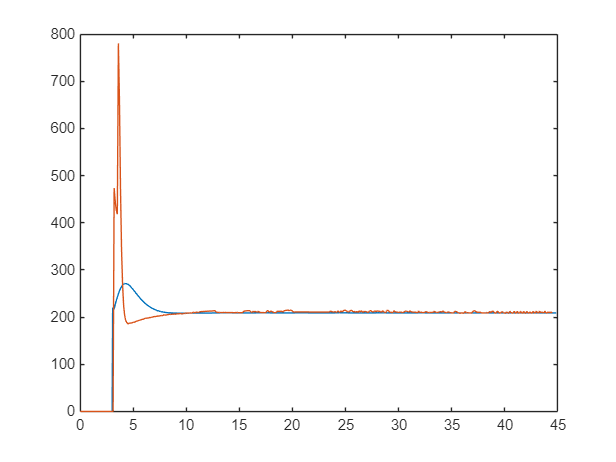

figure()

plot(out.main_clock, out.F_total(:, 3))
hold on
plot(t_final,torque_final)
hold off;




plotVariable(out.main_clock, out.T_total, "t [s]", "T [N/m]", "Torque")
plotVariable(out.main_clock, out.vehicle_position, "t [s]", "P [m]", "Vechicle Position")
plotVariable(out.main_clock, -out.vehicle_velocity(: , 3), "t [s]", "V [m/s]", "Vechicle Velocity")
plotVariable(out.main_clock, out.vehicle_orientation, "t [s]", "Euler [º]", "Vechicle Orientation")

#### ROTOR

plotVariable(out.main_clock, out.F_rotor, "t [s]", "F Rotor [N]", "Rotor Force")
plotVariable(out.main_clock, out.T_rotor, "t [s]", "T Rotor [N]", "Rotor Torque")
plotVariable(out.main_clock, out.rotor_velocity * 60 / (2*pi), "t [s]", "RPM", "Rotor Velocity")
plotVariable(out.main_clock, -out.rotor_induced_velocity, "t [s]", "V_i [m/s]", "Induced Velocity")

#### BLADE

t = 100;
azimute = 90;
[~, i] = min(abs(out.rotor_data.time - t));
data_rotor = out.rotor_data.data(i);
[~, i] = min(abs(data_rotor.azimutal_position - azimute));
data_blade = data_rotor.blade_distribution_data(i);
xx = (0:50) * (1/70) + 0;
azimutes = data_rotor.azimutal_position;

#### Element Frame

Nesta variável o  sinal de menos serve para criar concordância entre a direção do movimento

plotVariable(xx, -data_blade.dF_e_x, "x [m]", "F [N]", "X-force Element Frame")
plotVariable(xx, data_blade.dF_e_y, "x [m]", "F [N]", "y-force Element Frame")
plotVariable(xx, data_blade.dF_e_z, "x [m]", "F [N]", "z-force Element Frame")
plotVariable(xx, data_blade.U_P, "x [m]", "V [m/s]", "U_P Velocity")
plotVariable(xx, data_blade.U_T, "x [m]", "V [m/s]", "U_T Velocity")
plotVariable(xx, data_blade.U_R, "x [m]", "V [m/s]", "U_R Velocity")
plotVariable(xx, data_blade.theta, "x [m]", "\theta [º]", "Theta")
plotVariable(xx, data_blade.phi, "x [m]", "\phi [º]", "Phi")
plotVariable(xx, data_blade.alpha, "x [m]", "\alpha [o]", "Alpha")

plotVariable(xx, data_blade.f_prandtl, "x [m]", "\alpha [o]", "Alpha")

for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_i_x;
end
polarPlot(azimutes, xx, values, "", "F_z [N]", "")
for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_i_y;
end
polarPlot(azimutes, xx, values, "", "F_y [N]", "")
for i=1:length(azimutes)
    values(i, :) = data_rotor.blade_distribution_data(i).dF_i_z;
end
polarPlot(azimutes, xx, values, "", "F_z [N]", "")